# Load data

clear all; close all;
addpath('./MatlabFuncs/')

load('Data/Param_Fit2.mat', 'x_both', 'phi_s'); %%mac syntax

xdata = [0, .2, .5, 1, 2, 5, 10, 20, 50, 100];

run('./MatlabFuncs/FuncGenerator.m');

auxins = logspace(-2,2,100);

# Time Trajectories 

## *Varied initial Conditions*

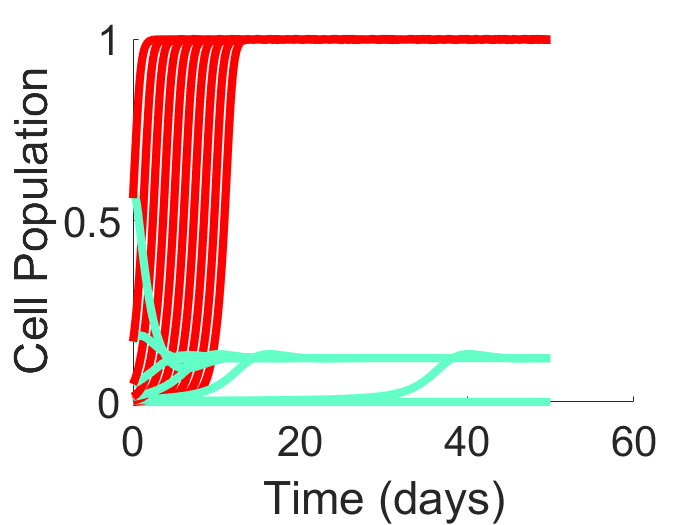

param = x_both; 
tspan = linspace(0, 50 * 24, 1000);

%Set known values
B_ext = 50; %ug
AP = 20; %uM

c0 = logspace(-5, -0.25, 10);
a0 = 10; %linspace(5,20,5);
[A1, N1] = meshgrid(a0,c0);

figure(1);

cir_on = [];
cir_off = [];

for i = 1 : numel(A1)
    y0 = [A1(i), N1(i)];
    [t,f] = ode45(@(t,y) DynSys_syn(t,y,param,phi_s,B_ext,AP),tspan,y0');
    [tc,fc] = ode45(@(t,y) DynSys_syn(t,y,param,phi_s,0,0),tspan,y0');
    
    cir_on = [cir_on, f(:,2)];
    cir_off = [cir_off, fc(:,2)];
    
    hold on;
    plot(tspan./24,f(:,2),'k','Linewidth',5,'Color',[100,255,201]./255)
    plot(tspan./24,fc(:,2),'k','Linewidth',5,'Color',[1,0,0])
end

save("Data\Dynamcs.mat", "cir_on", "cir_off", "tspan");

xlabel('Time (days)')
ylabel('Cell Population')

ax1 = gca;
ax1.FontSize = 25;

## *Paradoxical Feedback Response to Mutation*

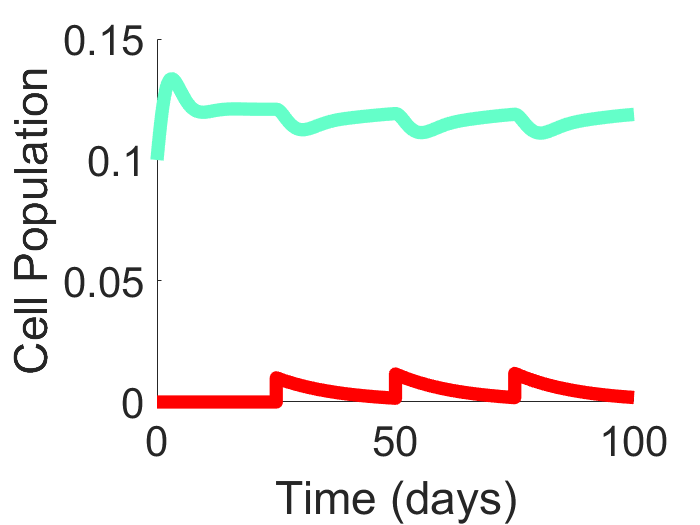

mutSpike = 0.01;

T = 25;
y0 = [10, 0.1, 0];

t_all1 = [];
f_all1 = [];
y0_t = y0;
for tp = [0,T,T*2,T*3]
    tspan1 = linspace(tp*24,(tp+T)*24,100);
    [t1,f1] = ode45(@(t,y) DynSys_syn_mut(t,y,param,phi_s,B_ext,AP),tspan1,y0_t');
    t_all1 = [t_all1; t1];
    f_all1 = [f_all1; f1];
    y0_t = f1(end,:) + [0, 0, mutSpike];
end


figure(2)
clf; hold on;

plot(t_all1./24, f_all1(:,2), 'LineWidth', 8, 'Color', [100,255,201]./255);
plot(t_all1./24, f_all1(:,3), 'LineWidth', 8, 'Color', [1,0,0]);

xlabel('Time (days)')
ylabel('Cell Population')
% xlim([0, 60])
ax2 = gca;
ax2.FontSize = 25;
box off;

## *Simple Feedback Response to Mutation*

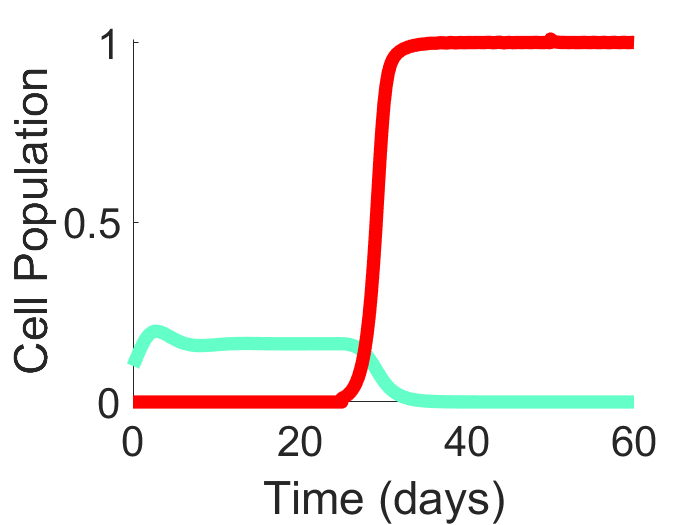

param_sf = param;
param_sf(2) = 0;


t_all2 = [];
f_all2 = [];
y0_t = y0;
for tp = [0,T,T*2,T*3]
    tspan1 = linspace(tp*24,(tp+T)*24,100);
    [t1,f1] = ode45(@(t,y) DynSys_syn_mut(t,y,param_sf,phi_s,B_ext,AP),tspan1,y0_t');
    t_all2 = [t_all2; t1];
    f_all2 = [f_all2; f1];
    y0_t = f1(end,:) + [0, 0, mutSpike];
end


save("Data\Dynamcs_mut1.mat", 't_all1', 'f_all1', "t_all2", 'f_all2')

figure(3)
clf; hold on;

plot(t_all2./24, f_all2(:,2), 'LineWidth', 8, 'Color', [100,255,201]./255);
plot(t_all2./24, f_all2(:,3), 'LineWidth', 8, 'Color', [1,0,0]);

xlabel('Time (days)')
ylabel('Cell Population')
xlim([0, 60])
ax3 = gca;
ax3.FontSize = 25;
box off;